clear all

frequency_accoustic = 80e9;
lambda_acoustic = 8433e6/frequency_accoustic;
% Optical Properties of Al at Probe Wavelength
n = 2.56;
k = 8.4646;
phi = atan((k*(n^2+k^2+1))/(n*(n^2+k^2-1)));
reflec_al = 0.875;
photoelastic_const_n = 0.0226 ;%0.0161;%0.0281;%0.2222/20;%-0.2222;
photoelastic_const_k = -0.0684 ;%-0.0501;%-0.0809;%0.5211/20;%0.5211/20;%0.5211;%0.5211;
f0 = 8*2*pi*sqrt((k^2*(n^2+k^2-1))+(n^2*(n^2+k^2+1)))/(lambda_acoustic*((n+1)^2+k^2));

% Optical properties of Si at probe wavelength
n_si = 3.71;
k_si = 0.0077;
phi_si = atan((k_si*(n_si^2+k_si^2+1))/(n_si*(n_si^2+k_si^2-1)));
reflec_si = 1;
photoelastic_const_n_si =  0.0026;
photoelastic_const_k_si = 0;
f0_si = 8*2*pi*sqrt((n_si^2*(n_si^2+k_si^2-1))+(k_si^2*(n_si^2+k_si^2+1)))/(lambda_acoustic*((n_si+1)^2+k_si^2));



r_aperture = 4.12;


t = 2.5;
f_sim_factor = [1.6755 2.0052 2.2033 3.0098 3.8570 7.9671];%[1.4097 1.6755 2.0052 2.2033 2.43 3.01 3.857 5.2411 6.3357 7.9671 10.6712];
m = [64 56 52 40 32 16];%[72 64 56 52 48 40 32 24 20 16 12];
f_sim = t*f_sim_factor;

A_nozones = pi*(5^2);
[A_pos_tot, A_neg_tot,A_tot] = calculate_zone_area(lambda_acoustic,m,r_aperture);

%  dat_no_FZP = load("surf_strain_noGauss_FZP_cant_ht2p5_Al.txt");
%  dat_no_FZP(:,2:end) = dat_no_FZP(:,2:end)/(A_tot(1)*1e-12); %Averaging Step
 reflectometry_no_FZP_dat = load("reflectometry_noFZP_cant_ht2p5_volavg_hwhm_probe_all_zones.txt");

%[t_travel_no_fzp,t_idx_no_fzp] = max(reflectometry_no_FZP_dat(:,1));
%  reflectometry_no_FZP_dat(:,2:end) = reflectometry_no_FZP_dat(:,2:end)/(A_nozones*1e-12); %Averaging Step
 reflectometry_no_FZP = [reflectometry_no_FZP_dat(:,1),...
     reflec_al*f0*((photoelastic_const_k*(reflectometry_no_FZP_dat(:,2)*cos(phi)+reflectometry_no_FZP_dat(:,3)*sin(phi))...
     +photoelastic_const_n*(reflectometry_no_FZP_dat(:,3)*cos(phi)-reflectometry_no_FZP_dat(:,2)*sin(phi))))];

 

% loading integral parameters and averaging them with area of positive
% zones

for i=1:length(f_sim)
    m_str = num2str(m(i));
    f_str = replace(num2str(f_sim_factor(i)),'.','p');
%     dat_Al_FZP(:,:,i) = load(strjoin(["surf_strain_FZP_cant_m"  m_str "_" f_str "f_ht2p5_Al.txt"],''));
%     dat_Al_FZP(:,2:end,i) = dat_Al_FZP(:,2:end,i)/(A_pos_tot(i)*1e-12); % Averaging step
%     dat_Si_FZP(:,:,i) = load(strjoin(["surf_strain_FZP_cant_m"  m_str "_" f_str "f_ht2p5_Al.txt"],''));
%     dat_Si_FZP(:,2:end,i) = dat_Si_FZP(:,2:end,i)/(A_neg_tot(i)*1e-12); % Averaging Step
    reflectometry_data(:,:,i) = load(strjoin(["reflectometry_FZP_cant_m" m_str "_" f_str "f_ht2p5_volavg_hwhm_probe_all_zones.txt"],''));
%     reflectometry_data(:,2:end,i) = reflectometry_data(:,2:end,i)./(A_pos_tot(i)*1e-12); % Averaging Step
end 

focal_depth_idx_for_fitting = [0 0 0 1 1 1];
count = 0;
 
for i=1:size(reflectometry_data,3)
%     dat_total(:,1,i) = dat_Al_FZP(:,1,i);
    reflectometry_total(:,1,i) = reflectometry_data(:,1,i);
    reflectometry_total_Al(:,1,i) = reflectometry_data(:,1,i);
    
    reflectometry_total_Si(:,1,i) = reflectometry_data(:,1,i);
%     for j=2:size(dat_Al_FZP,2)
%        dat_total(:,j,i) = reflec_al*dat_Al_FZP(:,j,i);%+ reflec_si*dat_Si_avg_param_FZP(:,j,i);      
%        
%     end
    reflectometry_total_Al(:,2,i) = f0*(photoelastic_const_k*(reflectometry_data(:,2,i)*cos(phi)+reflectometry_data(:,3,i)*sin(phi))+...
                                    photoelastic_const_n*(reflectometry_data(:,3,i)*cos(phi)-reflectometry_data(:,2,i)*sin(phi)));
    
    reflectometry_total_Si(:,2,i) =f0_si*(photoelastic_const_k_si*(reflectometry_data(:,4,i)*cos(phi_si)+reflectometry_data(:,5,i)*sin(phi_si))+...
                                    photoelastic_const_n_si*(reflectometry_data(:,5,i)*cos(phi_si)-reflectometry_data(:,4,i)*sin(phi_si)));
    reflectometry_total(:,2,i) = (reflec_al*reflectometry_total_Al(:,2,i))...
        + (reflec_si*reflectometry_total_Si(:,2,i));
    
    if focal_depth_idx_for_fitting(i) == 1
        count = count+1;
        reflectometry_fzp_Al_dat_cos(:,count) = reflectometry_data(:,2,i);
        reflectometry_fzp_Al_dat_sin(:,count) = reflectometry_data(:,3,i);
        reflectometry_fzp_Si_dat_cos(:,count) = reflectometry_data(:,4,i);
        reflectometry_fzp_Si_dat_sin(:,count) = reflectometry_data(:,5,i);
    end

        reflectometry_nofzp_cos = reflectometry_no_FZP_dat(:,2);
        reflectometry_nofzp_sin = reflectometry_no_FZP_dat(:,3);

end

% figure




 %f= [1.0277,2.0441,2.9963,3.9885,4.4048,4.8817,5.4357,6.8778,7.8496,9.0839];%,21.8984];%[1.4921,1.8482,2.0441,2.4812];
%t = 2.5;

## Estimating photoelastic constants of Al compared to Si

% Instructions  to use the functions
% [peak_peak_cos_Al_FZP_firstecho,peak_peak_sin_Al_FZP_firstecho,peak_peak_cos_Si_FZP_firstecho,...
%     peak_peak_sin_Si_FZP_firstecho,peak_peak_cos_Al_noFZP_firstecho,peak_peak_sin_Al_noFZP_firstecho] =...
%     extract_data_for_fitting(reflectometry_fzp_Al_dat_cos,reflectometry_fzp_Al_dat_sin,...
%     reflectometry_fzp_Si_dat_cos,reflectometry_fzp_Si_dat_sin,reflectometry_nofzp_cos,reflectometry_nofzp_sin...
%     ,f0,f0_si,phi,phi_si,reflec_al,reflec_si,n_obs)

% Extracting first echoes from measurement data

[t_travel,t_idx] = max(reflectometry_total(:,1,2));
[t_travel_no_fzp,t_idx_no_fzp] = max(reflectometry_no_FZP(:,1));
n_obs = 3;
home_dir = 'D:/experiment_pics/';
current_dir = 'D:/anisotropy/anisotropy_final';
cd(home_dir)
exp_echo_ratio = load("fitted_echoes_with_error_bar.txt");
exp_echo_ratio_norm = load("fitted_echoes_with_error_bar_norm.txt");
exp_echo_rbf_fit_norm = load("fitted_echo_amp_fzp_norm.txt");

exp_echo_rbf_fzp = load("fitted_echo_fzp_norm.mat")

exp_echo_rbf_fzp = struct with fields:
    Sig_rbf_high_res_FZP: {[399×2 double]  [399×2 double]  [399×2 double]  [399×2 double]}


exp_echo_rbf_nofzp = load("fitted_echo_nofzp_norm.mat")

exp_echo_rbf_nofzp = struct with fields:
    Sig_rbf_high_res_noFZP: {[399×2 double]  [399×2 double]  [399×2 double]  [399×2 double]}


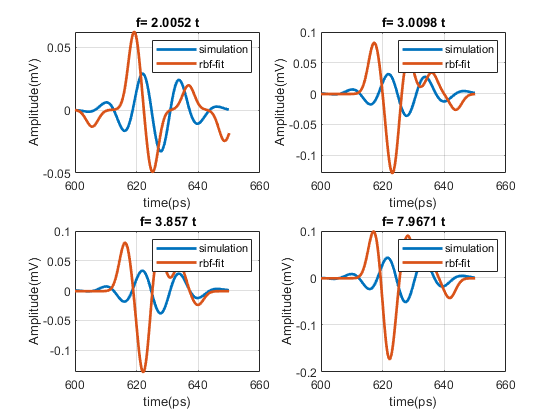

cd(current_dir)

idx = [2 4 5 6];

figure
for i=1:4
    subplot(2,2,i)
    t_range = reflectometry_total(:,1,idx(i))>6e-10 & reflectometry_total(:,1,idx(i))<6.5e-10;
   plot(reflectometry_total(t_range,1,idx(i))/1e-12,50*reflectometry_total(t_range,2,idx(i)),"LineWidth",2) 
   hold on
   %Shifting the start time of measurement data
   t_range_rbf(:,i) = exp_echo_rbf_fzp.Sig_rbf_high_res_FZP{i}(:,1) - (exp_echo_rbf_fzp.Sig_rbf_high_res_FZP{i}(1,1)-6e-10);
   plot(t_range_rbf(:,i)/1e-12,...
       exp_echo_rbf_fzp.Sig_rbf_high_res_FZP{i}(:,2),"LineWidth",2)
   xlabel("time(ps)")
   ylabel("Amplitude(mV)")
   legend(["simulation" "rbf-fit"])
   grid on
   title(strjoin(["f=" num2str(f_sim_factor(idx(i))) "t"]))
end




[peak_peak_cos_Al_FZP_amps,peak_peak_sin_Al_FZP_amps,peak_peak_cos_Si_FZP_amps,...
    peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,peak_peak_sin_Al_noFZP_amps] =...
    extract_data_for_fitting(reflectometry_fzp_Al_dat_cos,reflectometry_fzp_Al_dat_sin,...
    reflectometry_fzp_Si_dat_cos,reflectometry_fzp_Si_dat_sin,reflectometry_nofzp_cos,reflectometry_nofzp_sin...
    ,f0,f0_si,phi,phi_si,reflec_al,reflec_si,n_obs,t_idx,t_idx_no_fzp);


% [fitted_coef] = linear_regression_fit(peak_peak_cos_Al_FZP_amps(:,2),peak_peak_sin_Al_FZP_amps(:,2),...
%     peak_peak_cos_Si_FZP_amps(:,2),peak_peak_sin_Si_FZP_amps(:,2),peak_peak_cos_Al_noFZP_amps(:,2),...
%     peak_peak_sin_Al_noFZP_amps(:,2),exp_echo_ratio(2,2:end),...
%     photoelastic_const_n_si,photoelastic_const_k_si)

[photoelastic_const_Al_Si_FZP_ratio] = linear_regression_normalised_data_fit(peak_peak_cos_Al_FZP_amps,...
    peak_peak_sin_Al_FZP_amps,peak_peak_cos_Si_FZP_amps,peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,...
    peak_peak_sin_Al_noFZP_amps,exp_echo_ratio_norm(2,2:end),photoelastic_const_n_si,photoelastic_const_k_si)

photoelastic_const_Al_Si_FZP_ratio =    -0.0684
    0.0226


## Post-processing data for plotting


figure
for i=1:size(reflectometry_total,3)
    [t_travel(i),t_idx(i)] = max(reflectometry_total(:,1,i));
%     dat_excite_arr = dat_total(dat_total(:,1,i)<t_travel(i)/2,:,i);
%     dat_excite(1:size(dat_excite_arr,1),:,i) = dat_total(dat_total(:,1,i)<t_travel(i)/2,:,i);
    reflect_excite(:,:,i) = reflectometry_total(reflectometry_total(:,1,i)<t_travel(i)/2,:,i);
%     dat_short_arr = dat_total(dat_total(:,1,i)>t_travel(i)/2,:,i);
%     dat_short(1:size(dat_short_arr,1),:,i) = dat_total(dat_total(:,1,i)>t_travel(i)/2,:,i);
    reflect_short(:,:,i) = reflectometry_total(reflectometry_total(:,1,i)>t_travel(i)/2,:,i);
%     max_strain(i) = max(abs(dat_short(:,2,i)));
%     max_excite_strain(i) = max(abs(dat_excite(:,2,i)));
%     max_vz(i) = max(abs(dat_short(:,3,i)));
%     max_excite_vz(i) = max(abs(dat_excite(:,3,i)));
%     max_stress(i) = max(abs(dat_short(:,4,i)));
%     max_excite_stress(i) = max(abs(dat_excite(:,4,i)));
%     max_energy(i) = max(abs(dat_short(:,5,i)));
%     max_excite_energy(i) = max(abs(dat_excite(:,5,i)));
    max_reflect(i) = max((reflect_short(:,2,i))) - min((reflect_short(:,2,i)));
    max_reflect_excite(i) = max((reflect_excite(:,2,i))) - min((reflect_excite(:,2,i)));
    dat_excite_arr = [];
    dat_short_arr = [];
% % %     max_ke(i) = max(abs(dat_Al_short(:,7,i)));
% % %     max_excite_vzke(i) = max(abs(dat_Al_excite(:,7,i)));

end
dat_excite = [];
reflect_excite =[];
dat_short = [];
reflect_short = [];
% extracting data without fzp

[t_travel_no_fzp,t_idx_no_fzp] = max(reflectometry_no_FZP(:,1));
% dat_excite_arr = dat_no_FZP(dat_no_FZP(:,1)<t_travel_no_fzp/2,:);
% dat_excite(1:size(dat_excite_arr,1),:) = dat_no_FZP(dat_no_FZP(:,1)<t_travel_no_fzp/2,:);
reflect_excite = reflectometry_no_FZP(reflectometry_no_FZP(:,1)<t_travel_no_fzp/2,:);
% dat_short_arr = dat_no_FZP(dat_no_FZP(:,1)>t_travel_no_fzp/2,:);
% dat_short(1:size(dat_short_arr,1),:) = dat_no_FZP(dat_no_FZP(:,1)>t_travel_no_fzp/2,:);
reflect_short = reflectometry_no_FZP(reflectometry_no_FZP(:,1)>t_travel_no_fzp/2,:);
% max_strain_no_fzp = max(abs(dat_short(:,2)));
% max_excite_strain_no_fzp = max(abs(dat_excite(:,2)));
% max_vz_no_fzp = max(abs(dat_short(:,3)));
% max_excite_vz_no_fzp = max(abs(dat_excite(:,3)));
% max_stress_no_fzp = max(abs(dat_short(:,4)));
% max_excite_stress_no_fzp = max(abs(dat_excite(:,4)));
% max_energy_no_fzp = max(abs(dat_short(:,5)));
% max_excite_energy_no_fzp = max(abs(dat_excite(:,5)));
max_reflect_no_fzp = max((reflect_short(:,2))) - min((reflect_short(:,2)));
max_reflect_excite_no_fzp = max(abs(reflect_excite(:,2)))- min((reflect_excite(:,2)));



% Saving Max echo datas
% sim_echoes_with_fzp = [f_sim;max_strain;max_vz];
% sim_echoes_without_fzp = [max_strain_no_fzp;max_vz_no_fzp];
reflectometry_sim_echoes_with_fzp = [f_sim;max_reflect];
reflectometry_sim_echoes_without_fzp = [max_reflect_no_fzp];

% sim_echoes_with_fzp_norm = [f_sim;max_strain./max_excite_strain;max_vz./max_excite_vz];
% sim_echoes_without_fzp_norm = [max_strain_no_fzp./max_excite_strain_no_fzp;max_vz_no_fzp./max_excite_vz_no_fzp];
reflectometry_sim_echoes_with_fzp_norm = [f_sim;max_reflect./max_reflect_excite];
reflectometry_sim_echoes_without_fzp_norm = [max_reflect_no_fzp./max_reflect_excite_no_fzp];

% sim_echoes_with_fzp_avg_param = [f_sim_avg_param;avg_max_strain;avg_max_vz];
% sim_echoes_without_fzp_avg_param = [avg_max_strain_no_fzp;avg_max_vz_no_fzp];
% sim_echoes_with_fzp_avg_param_norm = [f_sim_avg_param;avg_max_strain./avg_max_excite_strain;avg_max_vz./avg_max_excite_vz];
% sim_echoes_without_fzp_avg_param_norm = [avg_max_strain_no_fzp./avg_max_excite_strain_no_fzp;avg_max_vz_no_fzp./avg_max_excite_vz_no_fzp];

## Saving data


home_dir = 'D:/experiment_pics/';
current_dir = 'D:/anisotropy/anisotropy_final';
cd(home_dir)
% save("sim_echoes_with_fzp.txt",'sim_echoes_with_fzp','-ascii')
% save("sim_echoes_without_fzp.txt",'sim_echoes_without_fzp','-ascii')
save("reflectometry_sim_echoes_with_fzp_Al_corr_allzones_f7.txt",'reflectometry_sim_echoes_with_fzp','-ascii')
save("reflectometry_sim_echoes_without_fzp_Al_corr_allzones_f7.txt",'reflectometry_sim_echoes_without_fzp','-ascii')

% save("sim_echoes_with_fzp_norm.txt",'sim_echoes_with_fzp_norm','-ascii')
% save("sim_echoes_without_fzp_norm.txt",'sim_echoes_without_fzp_norm','-ascii')
save("reflectometry_sim_echoes_with_fzp_norm_Al_corr_allzones_f7.txt",'reflectometry_sim_echoes_with_fzp_norm','-ascii')
save("reflectometry_sim_echoes_without_fzp_norm_Al_corr_allzones_f7.txt",'reflectometry_sim_echoes_without_fzp_norm','-ascii')

% save("sim_echoes_with_fzp_avg_param.txt",'sim_echoes_with_fzp_avg_param','-ascii')
% save("sim_echoes_without_fzp_avg_param.txt",'sim_echoes_without_fzp_avg_param','-ascii')
% 
% save("sim_echoes_with_fzp_avg_param_norm.txt",'sim_echoes_with_fzp_avg_param_norm','-ascii')
% save("sim_echoes_without_fzp_avg_param_norm.txt",'sim_echoes_without_fzp_avg_param_norm','-ascii')
cd(current_dir)


## FFT

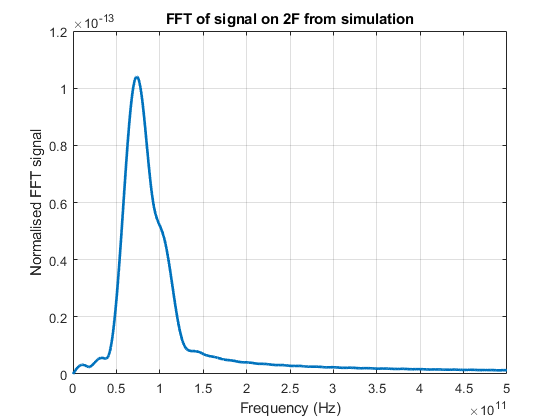

del_t = 6.1e-10 - 3.7125e-11;
time_window_size = 0.5e-10;

[f_FZP_2F_sim, Sig_FZP_2F] = take_fft(dat_total(:,1,1),dat_total(:,2,1),del_t,time_window_size);
[f_FZP_3F_sim, Sig_FZP_3F] = take_fft(dat_total(:,1,2),dat_total(:,2,2),del_t,time_window_size);
[f_FZP_4F_sim, Sig_FZP_4F] = take_fft(dat_total(:,1,3),dat_total(:,2,3),del_t,time_window_size);
[f_FZP_8F_sim, Sig_FZP_8F] = take_fft(dat_total(:,1,4),dat_total(:,2,4),del_t,time_window_size);



figure
plot(f_FZP_2F_sim,abs(Sig_FZP_2F),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on 2F from simulation")
% legend(["On FZP 8F" "Off FZP"])
grid on

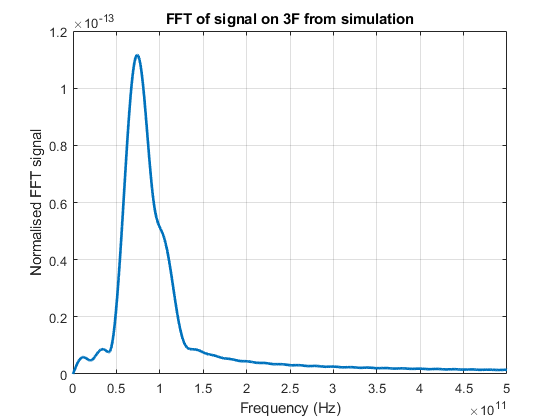

figure
plot(f_FZP_3F_sim,abs(Sig_FZP_3F),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on 3F from simulation")
% legend(["On FZP 8F" "Off FZP"])
grid on

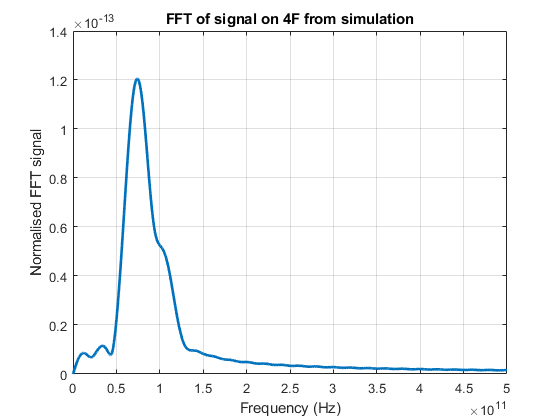


figure
plot(f_FZP_4F_sim,abs(Sig_FZP_4F),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on 4F from simulation")
% legend(["On FZP 8F" "Off FZP"])
grid on

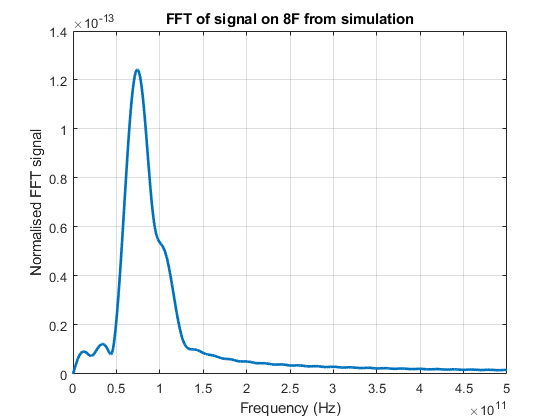


figure
plot(f_FZP_8F_sim,abs(Sig_FZP_8F),'LineWidth',2)
xlabel("Frequency (Hz)")
ylabel("Normalised FFT signal")
xlim([0 500e9])
title("FFT of signal on 8F from simulation")
% legend(["On FZP 8F" "Off FZP"])
grid on

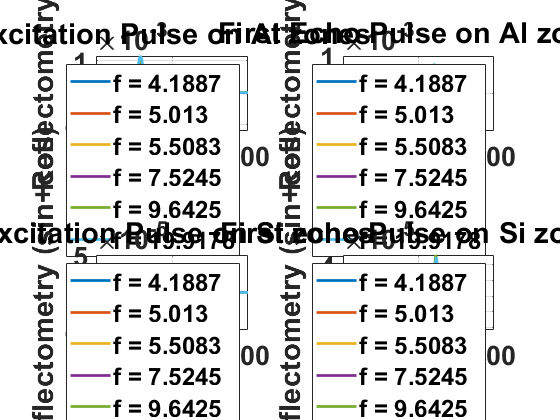

%% Plotting calculated echo amplitude
t = 2.5;

% figure
% subplot(2,2,1)
% for i=1:length(f_sim_factor)
% plot(dat_total(1:t_idx(i),1,i),dat_total(1:t_idx(i),2,i),"LineWidth",2);
% hold on
% end
% plot(dat_no_FZP(:,1),dat_no_FZP(:,2),"LineWidth",2);%,dat_Al(:,1,4),dat_Al(:,7,4),dat_Al(:,1,6),dat_Al(:,7,6)
% hold on
% grid on
% xlabel("time(s)")
% ylabel("Strain Surface Average")
% title("Excitation Pulse")
% legend([ strjoin(["f = " f_sim(1)],''), ...
%     strjoin(["f = " f_sim(2)],''), ...
%     strjoin(["f = " f_sim(3)],''), ...
%     strjoin(["f = " f_sim(4)],''), ...
%     strjoin(["f = " f_sim(5)],''), ...
%     strjoin(["f = " f_sim(6)],''), ...
%     "No FZP"])
% set(gca,'FontSize',16,'FontWeight','bold')
% xlim([0,1e-10])
% %legend(["f = 6.8878"])
% hold off
% subplot(2,2,2)
% for i=1:length(f_sim_factor)
% plot(dat_total(1:t_idx(i),1,i),dat_total(1:t_idx(i),2,i),"LineWidth",2);
% hold on
% end
% plot(dat_no_FZP(:,1),dat_no_FZP(:,2),"LineWidth",2);%,dat_Al(:,1,4),dat_Al(:,7,4),dat_Al(:,1,6),dat_Al(:,7,6)
% hold on
% grid on
% xlabel("time(s)")
% ylabel("Strain Surface Average")
% title("Reflection Pulse")
% legend([ strjoin(["f = " f_sim(1)],''), ...
%     strjoin(["f = " f_sim(2)],''), ...
%     strjoin(["f = " f_sim(3)],''), ...
%     strjoin(["f = " f_sim(4)],''), ...
%     strjoin(["f = " f_sim(5)],''), ...
%     strjoin(["f = " f_sim(6)],''), ...
%     "No FZP"])
% set(gca,'FontSize',16,'FontWeight','bold')
% xlim([5e-10,7e-10])
% %legend(["f = 6.8878"])
% hold off
% 
% subplot(2,2,3)
% for i=1:length(f_sim_factor)
% plot(dat_total(1:t_idx(i),1,i),dat_total(1:t_idx(i),2,i)./max_excite_strain(i),"LineWidth",2);
% hold on
% end
% plot(dat_no_FZP(:,1),dat_no_FZP(:,2)./max_excite_strain_no_fzp,"LineWidth",2);%,dat_Al(:,1,4),dat_Al(:,7,4),dat_Al(:,1,6),dat_Al(:,7,6)
% hold on
% grid on
% xlabel("time(s)")
% ylabel("Strain Surface Average (Normalised)")
% title("Normalised Excitation Pulse")
% legend([ strjoin(["f = " f_sim(1)],''), ...
%     strjoin(["f = " f_sim(2)],''), ...
%     strjoin(["f = " f_sim(3)],''), ...
%     strjoin(["f = " f_sim(4)],''), ...
%     strjoin(["f = " f_sim(5)],''), ...
%     strjoin(["f = " f_sim(6)],''), ...
%     "No FZP"])
% set(gca,'FontSize',16,'FontWeight','bold')
% xlim([0,1e-10])
% %legend(["f = 6.8878"])
% hold off
% subplot(2,2,4)
% for i=1:length(f_sim_factor)
% plot(dat_total(1:t_idx(i),1,i),dat_total(1:t_idx(i),2,i)./max_excite_strain(i),"LineWidth",2);
% hold on
% end
% plot(dat_no_FZP(:,1),dat_no_FZP(:,2)./max_excite_strain_no_fzp,"LineWidth",2);%,dat_Al(:,1,4),dat_Al(:,7,4),dat_Al(:,1,6),dat_Al(:,7,6)
% hold on
% grid on
% xlabel("time(s)")
% ylabel("Strain Surface Average (Normalised)")
% title("Normalised Reflection Pulse")
% legend([ strjoin(["f = " f_sim(1)],''), ...
%     strjoin(["f = " f_sim(2)],''), ...
%     strjoin(["f = " f_sim(3)],''), ...
%     strjoin(["f = " f_sim(4)],''), ...
%     strjoin(["f = " f_sim(5)],''), ...
%     strjoin(["f = " f_sim(6)],''), ...
%     "No FZP"])
% set(gca,'FontSize',16,'FontWeight','bold')
% xlim([5e-10,7e-10])
% ylim([-1 1])
% %legend(["f = 6.8878"])
% hold off

figure
subplot(2,2,1)
for i=1:length(f_sim_factor)
    plot(reflectometry_total_Al(1:t_idx(i),1,i)/1e-12,reflectometry_total_Al(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
%  plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(ps)")
ylabel("Reflectometry")
title("Excitation Pulse on Al zones")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],'')]) ...
%     "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([0,1e-10/1e-12])
% ylim([-0.03,0.03])
%legend(["f = 6.8878"])
hold off
subplot(2,2,2)
for i=1:length(f_sim_factor)
    plot(reflectometry_total_Al(1:t_idx(i),1,i)/1e-12,reflectometry_total_Al(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
% plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(ps)")
ylabel("Reflectometry")
title("First Echo Pulse on Al zones")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],'')]) ...
%     "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([5e-10/1e-12,7e-10/1e-12])
% ylim([-0.03,0.03])
%legend(["f = 6.8878"])
hold off

subplot(2,2,3)
for i=1:length(f_sim_factor)
    plot(reflectometry_total_Si(1:t_idx(i),1,i)/1e-12,reflectometry_total_Si(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
% plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(s)")
ylabel("Reflectometry (sin+cos)")
title(" Excitation Pulse on Si zones")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],'')]) ...
%     "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([0,1e-10/1e-12])
 ylim([-5e-5,5e-5])
%legend(["f = 6.8878"])
hold off
subplot(2,2,4)
for i=1:length(f_sim_factor)
    plot(reflectometry_total_Si(1:t_idx(i),1,i)/1e-12,reflectometry_total_Si(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
% plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(s)")
ylabel("Reflectometry (sin+cos)")
title("First echo Pulse on Si zones")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],'')]) ...
%     "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
%ylim([-0.03,0.03])
xlim([5e-10/1e-12,7e-10/1e-12])
%legend(["f = 6.8878"])
hold off

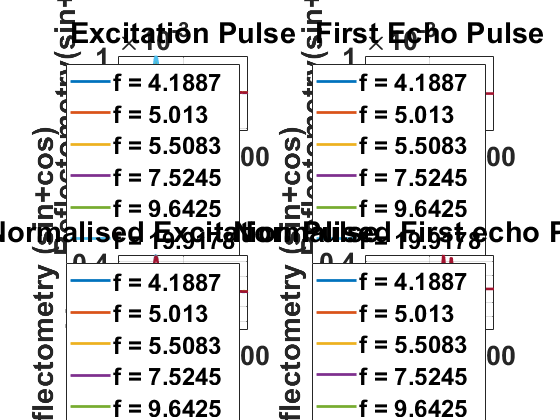




figure
subplot(2,2,1)
for i=1:length(f_sim_factor)
    plot(reflectometry_total(1:t_idx(i),1,i)/1e-12,reflectometry_total(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(ps)")
ylabel("Reflectometry(sin+cos)")
title("Excitation Pulse")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],''), ...
    "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([0,1e-10/1e-12])
%legend(["f = 6.8878"])
hold off
subplot(2,2,2)
for i=1:length(f_sim_factor)
    plot(reflectometry_total(1:t_idx(i),1,i)/1e-12,reflectometry_total(1:t_idx(i),2,i),"LineWidth",2)
    hold on
end
plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2),"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(ps)")
ylabel("Reflectometry(sin+cos)")
title("First Echo Pulse")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],''), ...
    "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([5e-10/1e-12,7e-10/1e-12])
%legend(["f = 6.8878"])
hold off

subplot(2,2,3)
for i=1:length(f_sim_factor)
    plot(reflectometry_total(1:t_idx(i),1,i)/1e-12,reflectometry_total(1:t_idx(i),2,i)/max_reflect_excite(i),"LineWidth",2)
    hold on
end
plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2)./max_reflect_excite_no_fzp,"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(s)")
ylabel("Reflectometry (sin+cos)")
title("Normalised Excitation Pulse")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],'')]) ...
    %"No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
xlim([0,1e-10/1e-12])
% ylim([-2,2])
%legend(["f = 6.8878"])
hold off
subplot(2,2,4)
for i=1:length(f_sim_factor)
    plot(reflectometry_total(1:t_idx(i),1,i)/1e-12,reflectometry_total(1:t_idx(i),2,i)/max_reflect_excite(i),"LineWidth",2)
    hold on
end
plot(reflectometry_no_FZP(:,1)/1e-12,reflectometry_no_FZP(:,2)./max_reflect_excite_no_fzp,"LineWidth",2);%,reflectometry_Al(:,1,4),reflectometry_Al(:,7,4),reflectometry_Al(:,1,6),reflectometry_Al(:,7,6)
hold on
grid on
xlabel("time(s)")
ylabel("Reflectometry (sin+cos)")
title("Normalised First echo Pulse")
legend([ strjoin(["f = " f_sim(1)],''), ...
    strjoin(["f = " f_sim(2)],''), ...
    strjoin(["f = " f_sim(3)],''), ...
    strjoin(["f = " f_sim(4)],''), ...
    strjoin(["f = " f_sim(5)],''), ...
    strjoin(["f = " f_sim(6)],''), ...
    "No FZP"])
set(gca,'FontSize',20,'FontWeight','bold')
% ylim([-2,2])
xlim([5e-10/1e-12,7e-10/1e-12])
%legend(["f = 6.8878"])
hold off

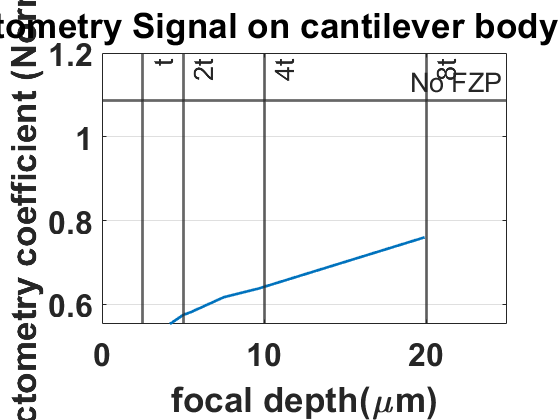



% figure
% plot(f_sim,max_strain./max_excite_strain,"LineWidth",2)
% grid on
% xline(t,"-","t")
% xline(2*t,"-","2t")
% xline(4*t,"-","4t")
% xline(8*t,"-","8t")
% yline(max_strain_no_fzp./max_excite_strain_no_fzp,"-","No FZP")
%  set(gca,'FontSize',20,'FontWeight','bold')
% % fontsize(gcf,scale=4)
% xlim([0 25])
% xlabel("focal depth(\mum)")
% ylabel("Normalised Strain ")
% % legend(["normalised strain integral" "normalised strain average"])
% title("Surface Integral of strain of the reflected acoustic signal")

fontsize = 20;
figure
plot(f_sim,max_reflect./(max_reflect_excite),"LineWidth",2)
grid on
xline(t,"-","t","FontSize",fontsize,"LineWidth",2)
xline(2*t,"-","2t","FontSize",fontsize,"LineWidth",2)
xline(4*t,"-","4t","FontSize",fontsize,"LineWidth",2)
xline(8*t,"-","8t","FontSize",fontsize,"LineWidth",2)
set(gca,'FontSize',24,'FontWeight','bold')
xlim([0 25])
xlabel("focal depth(\mum)")
ylabel("Reflectometry coefficient (Normalised)")
yline(max_reflect_no_fzp./(max_reflect_excite_no_fzp),"-","No FZP","FontSize",fontsize,"LineWidth",2)
% legend(["normalised strain integral" "normalised strain average"])
title("Normalised Reflectometry Signal on cantilever body vs focal depth of FZP")

## Checking 50 Ghz excitation with 80 GHz lens

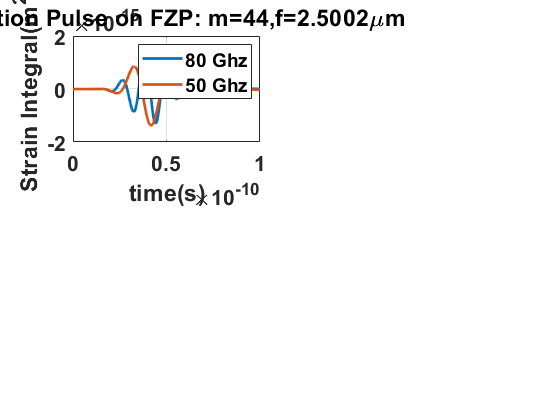

clear all

data_reflectometry_50Ghz = load("reflectometry_FZP_cant_2p0052f_data_Al_50Ghz_excitation.txt");
data_reflectometry = load("reflectometry_FZP_cant_2p0052f_data_Al.txt");

data_Al = load("FZP_cant_2p0052f_data_Al.txt");
data_Al_50Ghz = load("FZP_cant_2p0052f_data_Al_50Ghz_excitation.txt");

figure
subplot(2,2,1)
plot(data_Al(:,1),data_Al(:,2),data_Al_50Ghz(:,1),data_Al_50Ghz(:,2),"Linewidth",2)
xlabel("time(s)")
ylabel("Strain Integral(m^2)")
title("Excitation Pulse on FZP: m=44,f=2.5002\mum")
set(gca,'FontSize',16,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on
u_lim = 0; l_lim = 1e-10;
xlim([u_lim,l_lim])

max_val = max(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));

Unrecognized function or variable 'data_surf_int'.

min_val = min(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
peak_peak_ex_strain = max_val-min_val;

subplot(2,2,2)
plot(data_Al(:,1),data_Al(:,2),data_Al_50Ghz(:,1),data_Al_50Ghz(:,2),"Linewidth",2)
xlabel("time(s)")
ylabel("Strain Integral(m^2)")
title("First Echo pulse on FZP: m=44,f=2.5002\mum")
set(gca,'FontSize',16,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on
u_lim = 0; l_lim = 1e-10;
xlim([u_lim,l_lim])
max_val = max(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
min_val = min(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
peak_peak_ref_strain = max_val-min_val;

subplot(2,2,3)
plot(data_reflectometry(:,1),data_reflectometry(:,2)+data_reflectometry(:,3),...
    data_reflectometry_50Ghz(:,1),data_reflectometry_50Ghz(:,2)+data_reflectometry_50Ghz(:,3),"Linewidth",2)
xlabel("time(s)")
ylabel("Reflectometry Coefficient (cos+sin)")
title("Excitation Pulse: m=44,f=2.5002\mum")
set(gca,'FontSize',16,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on
u_lim = 0; l_lim = 1e-10;
xlim([u_lim,l_lim])
max_val = max(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
min_val = min(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
peak_peak_ex_ref = max_val-min_val;

subplot(2,2,4)
plot(data_reflectometry(:,1),data_reflectometry(:,2)+data_reflectometry(:,3),...
    data_reflectometry_50Ghz(:,1),data_reflectometry_50Ghz(:,2)+data_reflectometry_50Ghz(:,3),"Linewidth",2)
xlabel("time(s)")
ylabel("Reflectometry Coefficient (cos+sin)")
title("Reflection Pulse: m=44,f=2.5002\mum")
set(gca,'FontSize',16,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on
u_lim = 0; l_lim = 1e-10;
xlim([u_lim,l_lim])
max_val = max(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
min_val = min(data_surf_int_reflec((data_surf_int(:,1)>u_lim & data_surf_int(:,1)<l_lim),2));
peak_peak_ref_ref = max_val-min_val;

axial_data_50Ghz = load("axial_dist_m88_fm_2.5002_ht_2.5_vol_int_50Ghz_excitation.txt");
axial_data_80Ghz = load("axial_dist_m88_fm_2.5002_ht_2.5_vol_int.txt");

figure
plot(axial_data_80Ghz(:,1),axial_data_80Ghz(:,3),...
    axial_data_50Ghz(:,1),axial_data_50Ghz(:,3),"Linewidth",1)
xlabel("time(s)")
ylabel("Normal Velocity(m/s)")
title("Maximum particle velocity in z on FZP: m=44,f=2.5002\mum")
set(gca,'FontSize',16,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on

figure
plot(axial_data_80Ghz(:,1),axial_data_80Ghz(:,2),...
    axial_data_50Ghz(:,1),axial_data_50Ghz(:,2),"Linewidth",1)
xlabel("time(s)")
ylabel("Depth in z(\mum)")
title("Depth for Maximum Particle Velocity on FZP: m=44,f=2.5002\mum")
set(gca,'FontSize',20,'FontWeight','bold')
legend(["80 Ghz" "50 Ghz"])
grid on


## Functions

function [f_sig, S_sig] = take_fft(tot_first_echo_time_sig,tot_first_echo_sig,del_t,time_window_size)

    [first_echo_time_sig,first_echo_sig] = extract_first_echo(tot_first_echo_time_sig,tot_first_echo_sig,del_t,time_window_size); 
    
    pad_length = 4^nextpow2(length(first_echo_time_sig));
    
    f_sig = 0:1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)))...
        :(1/(first_echo_time_sig(2)-first_echo_time_sig(1)))-1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)));
        
    S_sig = fft(first_echo_sig,pad_length);
    
      

end

function [first_echo_time_sig,first_echo_sig_zero_mean] = extract_first_echo(tot_first_echo_time_sig,tot_first_echo_sig,del_t,time_window_size) 
%     file = load([home_dir '/' date '/' name '.mat']);
    data = tot_first_echo_sig;
    data_time = tot_first_echo_time_sig;
    
    [th_peak,ind] = max(data);
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig = data(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_time_sig = data_time(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_sig_zero_mean = first_echo_sig-mean(first_echo_sig); 
end

function [A_pos_tot, A_neg_tot,A_tot] = calculate_zone_area(lambda,m,r_aperture)
    for i=1:size(m,2)
        [y_pos_offset,r_n{i},incident_ex,fm(i),min_cut(i)] = f_zonal_plate_construction(lambda,m(i),1,r_aperture);
        r1(i) = r_n{i}(2);

        for j=1:(size(r_n{i},2)-1)/2
            A_pos(j,i) = -pi*(r_n{i}(2*j-1)^2-r_n{i}(2*j)^2);
            A_neg(j,i) = -pi*(r_n{i}(2*j)^2-r_n{i}(2*j+1)^2);
        end
        
        A_pos_tot(i)= sum(A_pos(:,i));
        A_neg_tot(i) = sum(A_neg(:,i));
        A_tot(i) = pi*(max(r_n{i})^2);
        
    end
end

function [peak_peak_cos_Al_FZP_amps,peak_peak_sin_Al_FZP_amps,peak_peak_cos_Si_FZP_amps,...
    peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,peak_peak_sin_Al_noFZP_amps] =...
    extract_data_for_fitting(reflectometry_fzp_Al_dat_cos,reflectometry_fzp_Al_dat_sin,...
    reflectometry_fzp_Si_dat_cos,reflectometry_fzp_Si_dat_sin,reflectometry_nofzp_Al_dat_cos,reflectometry_nofzp_Al_dat_sin...
    ,f0,f0_Si,phi,phi_Si,reflec_al,reflec_si,n_obs,t_idx,t_idx_no_fzp)

   
    for i=1:n_obs
        % Extracting cosine and sine terms
        reflectometry_total_Al_cos(:,i) = f0*reflec_al*((reflectometry_fzp_Al_dat_cos(:,i)*cos(phi)+reflectometry_fzp_Al_dat_sin(:,i)*sin(phi)));
        peak_peak_cos_Al_FZP_excite(i) = max(reflectometry_total_Al_cos(1:floor(t_idx/2)))-min(reflectometry_total_Al_cos(1:floor(t_idx/2)));
        peak_peak_cos_Al_FZP_firstecho(i) = max(reflectometry_total_Al_cos(floor(t_idx/2):end))-min(reflectometry_total_Al_cos(floor(t_idx/2):end));
        peak_peak_cos_Al_FZP(i) =   peak_peak_cos_Al_FZP_excite(i)/peak_peak_cos_Al_FZP_firstecho(i);
        peak_peak_cos_Al_FZP_amps(i,:) = [peak_peak_cos_Al_FZP_excite(i) peak_peak_cos_Al_FZP_firstecho(i)];
        
        reflectometry_total_Al_sin(:,i) = f0*reflec_al*((reflectometry_fzp_Al_dat_cos(:,i)*sin(phi)-reflectometry_fzp_Al_dat_sin(:,i)*cos(phi)));
        peak_peak_sin_Al_FZP_excite(i) = max(reflectometry_total_Al_sin(1:floor(t_idx/2)))-min(reflectometry_total_Al_sin(1:floor(t_idx/2)));
        peak_peak_sin_Al_FZP_firstecho(i) = max(reflectometry_total_Al_sin(floor(t_idx/2):end))-min(reflectometry_total_Al_sin(floor(t_idx/2):end));
        peak_peak_sin_Al_FZP(i) =   peak_peak_sin_Al_FZP_excite(i)/peak_peak_sin_Al_FZP_firstecho(i);
        peak_peak_sin_Al_FZP_amps(i,:) = [peak_peak_sin_Al_FZP_excite(i) peak_peak_sin_Al_FZP_firstecho(i)];
        
        reflectometry_total_Si_cos(:,i) = f0_Si*reflec_si*((reflectometry_fzp_Si_dat_cos(:,i)*cos(phi_Si)+reflectometry_fzp_Si_dat_sin(:,i)*sin(phi_Si)));
        peak_peak_cos_Si_FZP_excite(i) = max(reflectometry_total_Si_cos(1:floor(t_idx/2)))-min(reflectometry_total_Si_cos(1:floor(t_idx/2)));
        peak_peak_cos_Si_FZP_firstecho(i) = max(reflectometry_total_Si_cos(floor(t_idx/2):end))-min(reflectometry_total_Si_cos(floor(t_idx/2):end));
        peak_peak_cos_Si_FZP(i) =   peak_peak_cos_Si_FZP_excite(i)/peak_peak_cos_Si_FZP_firstecho(i);
        peak_peak_cos_Si_FZP_amps(i,:) = [peak_peak_cos_Si_FZP_excite(i) peak_peak_cos_Si_FZP_firstecho(i)];
        
        reflectometry_total_Si_sin(:,i) = f0_Si*reflec_si*((reflectometry_fzp_Si_dat_cos(:,i)*sin(phi_Si)-reflectometry_fzp_Si_dat_sin(:,i)*cos(phi_Si)));
        peak_peak_sin_Si_FZP_excite(i) = max(reflectometry_total_Si_sin(1:floor(t_idx/2)))-min(reflectometry_total_Si_sin(1:floor(t_idx/2)));
        peak_peak_sin_Si_FZP_firstecho(i) = max(reflectometry_total_Si_sin(floor(t_idx/2):end))-min(reflectometry_total_Si_sin(floor(t_idx/2):end));
        peak_peak_sin_Si_FZP(i) =   peak_peak_sin_Si_FZP_excite(i)/peak_peak_sin_Si_FZP_firstecho(i);
        peak_peak_sin_Si_FZP_amps(i,:) = [peak_peak_sin_Si_FZP_excite(i) peak_peak_sin_Si_FZP_firstecho(i)];

    end
    reflectometry_nofzp_cos = f0*reflec_al*((reflectometry_nofzp_Al_dat_cos*cos(phi)+reflectometry_nofzp_Al_dat_sin*sin(phi)));
    peak_peak_cos_Al_noFZP_excite = max(reflectometry_nofzp_cos(1:floor(t_idx_no_fzp/2)))-min(reflectometry_nofzp_cos(1:floor(t_idx_no_fzp/2)));
    peak_peak_cos_Al_noFZP_firstecho = max(reflectometry_nofzp_cos(floor(t_idx_no_fzp/2):end))-min(reflectometry_nofzp_cos(floor(t_idx_no_fzp/2):end));
    peak_peak_cos_Al_noFZP =   peak_peak_cos_Al_noFZP_excite/peak_peak_cos_Al_noFZP_firstecho;
    peak_peak_cos_Al_noFZP_amps(1,:) = [peak_peak_cos_Al_noFZP_excite(1) peak_peak_cos_Al_noFZP_firstecho(1)];
    
    reflectometry_nofzp_sin = f0*reflec_si*((reflectometry_nofzp_Al_dat_sin*cos(phi)-reflectometry_nofzp_Al_dat_cos*sin(phi)));
    peak_peak_sin_Al_noFZP_excite = max(reflectometry_nofzp_sin(1:floor(t_idx_no_fzp/2)))-min(reflectometry_nofzp_sin(1:floor(t_idx_no_fzp/2)));
    peak_peak_sin_Al_noFZP_firstecho = max(reflectometry_nofzp_sin(floor(t_idx_no_fzp/2):end))-min(reflectometry_nofzp_sin(floor(t_idx_no_fzp/2):end));
    peak_peak_sin_Al_noFZP =   peak_peak_sin_Al_noFZP_excite/peak_peak_sin_Al_noFZP_firstecho;
    peak_peak_sin_Al_noFZP_amps(1,:) = [peak_peak_sin_Al_noFZP_excite(1) peak_peak_sin_Al_noFZP_firstecho(1)];

end

function [fitted_coef] = linear_regression_fit(peak_peak_cos_Al_FZP,peak_peak_sin_Al_FZP,...
    peak_peak_cos_Si_FZP,peak_peak_sin_Si_FZP,peak_peak_cos_Al_noFZP,peak_peak_sin_Al_noFZP,exp_echo_ratio,...
    photoelastic_const_n_si,photoelastic_const_k_si)

exp_echo_ratio_w_excitation = exp_echo_ratio'/1.2;

C = [peak_peak_cos_Al_FZP-exp_echo_ratio_w_excitation*peak_peak_cos_Al_noFZP  peak_peak_sin_Al_FZP-exp_echo_ratio_w_excitation*peak_peak_sin_Al_noFZP];
d = -1*[photoelastic_const_k_si*peak_peak_cos_Si_FZP + photoelastic_const_n_si*peak_peak_sin_Si_FZP];

lb = -ones(2,1);
ub = ones(2,1);
x0 = [];
fitted_coef = inv(C'*C)*C'*d;
%options = optimoptions('lsqlin','Algorithm','interior-point');
% tic
% [fitted_coef,resnorm,residual,exitflag,output,lambda] = lsqlin(C,d,[],[],[],[],lb,ub,x0);
% toc
end

function [photoelastic_const_Al_FZP] = linear_regression_normalised_data_fit(peak_peak_cos_Al_FZP_amps,peak_peak_sin_Al_FZP_amps,...
    peak_peak_cos_Si_FZP_amps,peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,peak_peak_sin_Al_noFZP_amps,exp_echo_ratio,photoelastic_const_n_si,photoelastic_const_k_si)

exp_echo_ratio_w_excitation = exp_echo_ratio'*1.08;

C(:,1) = peak_peak_cos_Al_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_cos_Al_FZP_amps(:,1);
C(:,2) = peak_peak_sin_Al_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_sin_Al_FZP_amps(:,1);


d = -1*(photoelastic_const_k_si*(peak_peak_cos_Si_FZP_amps(:,2)-exp_echo_ratio_w_excitation.*peak_peak_cos_Si_FZP_amps(:,1))+...
    photoelastic_const_n_si*(peak_peak_sin_Si_FZP_amps(:,2)-exp_echo_ratio_w_excitation.*peak_peak_sin_Si_FZP_amps(:,1)));

lb = -ones(2,1);
ub = ones(2,1);
x0 = [];
photoelastic_const_Al_FZP = inv(C'*C)*C'*d;
%options = optimoptions('lsqlin','Algorithm','interior-point');
% tic
% [fitted_coef,resnorm,residual,exitflag,output,lambda] = lsqlin(C,d,[],[],[],[],lb,ub,x0);
% toc
end

function [photoelastic_const_Al_Si_ratio_FZP] = linear_regression_normalised_data_fit3(peak_peak_cos_Al_FZP_amps,peak_peak_sin_Al_FZP_amps,...
    peak_peak_cos_Si_FZP_amps,peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,peak_peak_sin_Al_noFZP_amps,exp_echo_ratio,photoelastic_const_n_si,photoelastic_const_k_si)

exp_echo_ratio_w_excitation = exp_echo_ratio'*1.08;

C(:,1) = peak_peak_sin_Al_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_sin_Al_FZP_amps(:,1);
C(:,2) = peak_peak_cos_Si_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_cos_Si_FZP_amps(:,1);
C(:,3) = peak_peak_sin_Si_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_sin_Si_FZP_amps(:,1);


d = -1*(peak_peak_cos_Al_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_cos_Al_FZP_amps(:,1));

lb = -ones(3,1);
ub = ones(3,1);
x0 = [];
photoelastic_const_Al_Si_ratio_FZP = inv(C'*C)*C'*d;
%options = optimoptions('lsqlin','Algorithm','interior-point');
% tic
% [fitted_coef,resnorm,residual,exitflag,output,lambda] = lsqlin(C,d,[],[],[],[],lb,ub,x0);
% toc
end

function [photoelastic_const_Al_Si_ratio_FZP] = nonlinear_regression_normalised_data_fit3(peak_peak_cos_Al_FZP_amps,peak_peak_sin_Al_FZP_amps,...
    peak_peak_cos_Si_FZP_amps,peak_peak_sin_Si_FZP_amps,peak_peak_cos_Al_noFZP_amps,peak_peak_sin_Al_noFZP_amps,exp_echo_ratio,photoelastic_const_n_si,photoelastic_const_k_si)

exp_echo_ratio_w_excitation = exp_echo_ratio';
r(:,1) = peak_peak_sin_Al_FZP_amps(:,2);
r(:,2) = peak_peak_cos_Al_FZP_amps(:,2);
r(:,3) = peak_peak_sin_Si_FZP_amps(:,2);
r(:,4) = peak_peak_cos_Si_FZP_amps(:,2);
r(:,5) = peak_peak_sin_Al_noFZP_amps(:,2);
r(:,6) = peak_peak_cos_Al_noFZP_amps(:,2);


e(:,1) = peak_peak_sin_Al_FZP_amps(:,1);
e(:,2) = peak_peak_cos_Al_FZP_amps(:,1);
e(:,3) = peak_peak_sin_Si_FZP_amps(:,1);
e(:,4) = peak_peak_cos_Si_FZP_amps(:,1);
e(:,5) = peak_peak_sin_Al_noFZP_amps(:,1);
e(:,6) = peak_peak_cos_Al_noFZP_amps(:,1);

a3 = photoelastic_const_n_si;
a4 = photoelastic_const_k_si;

%fun= @(a)(a(1).*(peak_peak_sin_Al_FZP_amps(:,2))+a(2).*(peak_peak_cos_Al_FZP_amps(:,2))+a3.*(peak_peak_sin_Si_FZP_amps(:,2))+a4.*(peak_peak_cos_Si_FZP_amps(:,2)))

d = -1*(peak_peak_cos_Al_FZP_amps(:,2) - exp_echo_ratio_w_excitation.*peak_peak_cos_Al_FZP_amps(:,1));

lb = -ones(3,1);
ub = ones(3,1);
x0 = [];
photoelastic_const_Al_Si_ratio_FZP = inv(C'*C)*C'*d;
%options = optimoptions('lsqlin','Algorithm','interior-point');
% tic
% [fitted_coef,resnorm,residual,exitflag,output,lambda] = lsqlin(C,d,[],[],[],[],lb,ub,x0);
% toc
end